# Linear Algebra Project 1 - Q1 - 810101477

Least Squares Regression Live Script

This live script walks through generating synthetic data, performing least

squares regression, ridge regularization, and constrained models.

Sections A-F correspond to the assignment guidelines.

### A. Synthetic Data & Initial Exploration

We first generate a training set of N = 200 samples in ℝ³⁰ by drawing each feature from a Weibull distribution (shape k = 2, scale λ = 1) and sample corresponding targets y from a Poisson(μ = 5). Histograms of the marginal distributions of X and y confirm that our simulation matches the intended stochastic models, and the cross‐correlation between y and the first feature of X provides an initial look at any linear dependencies before fitting a model.

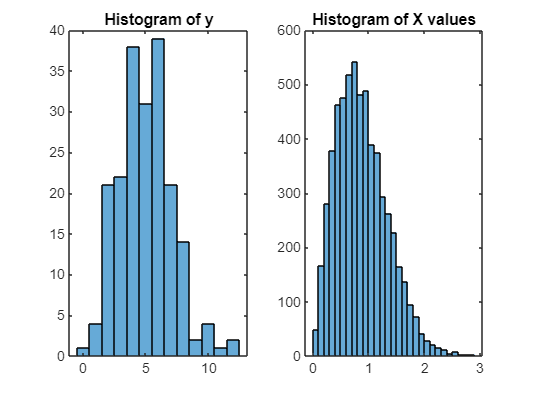

rng(0); % For reproducibility
n = 30; N = 200;
% Weibull parameters: shape k=2, scale lambda=1
k = 2; lambda_w = 1;
X = wblrnd(lambda_w, k, N, n);
% Poisson with mean mu=5
mu = 5;
y = poissrnd(mu, N, 1);

% Plot histograms
figure; 
subplot(1,2,1);
histogram(y);
title('Histogram of y');
subplot(1,2,2);
histogram(X(:));
title('Histogram of X values');

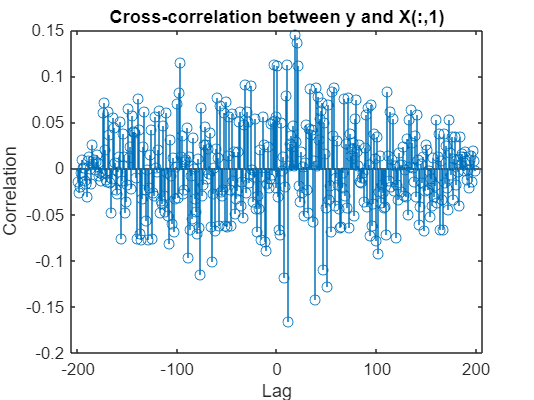


% Cross-correlation between y and first feature of X
figure;
[xcorrVals, lags] = xcorr(y - mean(y), X(:,1) - mean(X(:,1)), 'coeff');
stem(lags, xcorrVals);
title('Cross-correlation between y and X(:,1)');
xlabel('Lag'); ylabel('Correlation');

### B. Small‐Sample Test Set & Comparison

To evaluate out‐of‐sample performance under limited data, we generate an independent test set of N_test = 20 with the same Weibull and Poisson parameters. Repeating histograms and cross‐correlation plots on this smaller sample highlights the increased sampling variability and potential overfitting pitfalls when data are scarce.

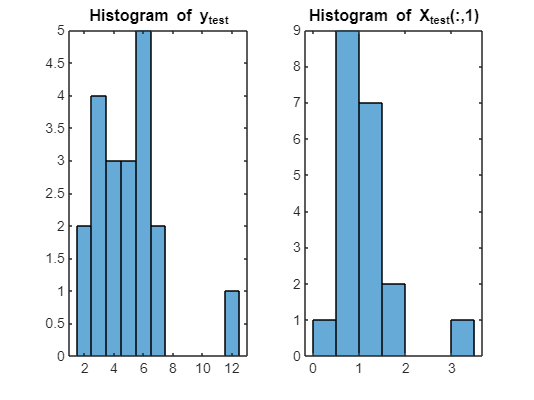

rng(1);
Ntest = 20;
Xtest = wblrnd(lambda_w, k, Ntest, n);
ytest = poissrnd(mu, Ntest, 1);

figure;
subplot(1,2,1);
histogram(ytest);
title('Histogram of y_{test}');
subplot(1,2,2);
histogram(Xtest(:,1));
title('Histogram of X_{test}(:,1)');

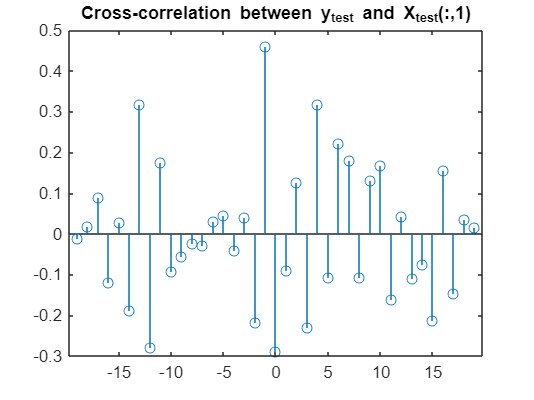


figure;
[xcTest, lagsTest] = xcorr(ytest - mean(ytest), Xtest(:,1) - mean(Xtest(:,1)), 'coeff');
stem(lagsTest, xcTest);
title('Cross-correlation between y_{test} and X_{test}(:,1)');

### C. Ordinary Least Squares (OLS)

We fit a linear model with intercept by solving the normal equations to minimize the sum of squared errors on the training set. This baseline OLS solution yields coefficients (β,ν) that we then use to predict both training and test responses, reporting the corresponding mean squared errors to benchmark subsequent regularized models.

X1 = [X, ones(N,1)];
beta_nu = X1 \ y;   % solves [beta; nu]
beta = beta_nu(1:n);
nu = beta_nu(end);

% Predictions
y_pred_train = X*beta + nu;
MSE_train = mean((y - y_pred_train).^2);

y_pred_test = Xtest*beta + nu;
MSE_test = mean((ytest - y_pred_test).^2);

fprintf('OLS Train MSE: %.4f\n', MSE_train);

OLS Train MSE: 3.7591


fprintf('OLS Test MSE:  %.4f\n', MSE_test);

OLS Test MSE:  6.3708


### D. Ridge Regression (ℓ₂ Penalty)

Introducing an ℓ₂ penalty on the coefficient vector β (excluding the intercept) controls model complexity and variance. We let λ = σ vary logarithmically from exp(–4) to exp(4), solve the modified normal equations for each σ, and plot the training and test MSE curves. The resulting U‐shaped tradeoff illustrates how increasing regularization reduces variance but induces bias.

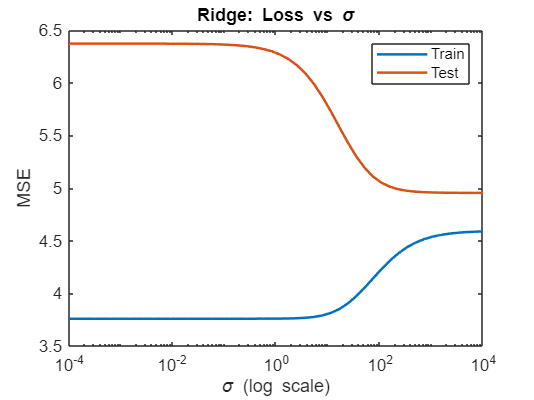

sigmas = logspace(-4, 4, 50);
train_loss = zeros(size(sigmas));
test_loss = zeros(size(sigmas));
for i = 1:length(sigmas)
    sigma = sigmas(i);
    L = sigma * eye(n+1);
    L(end,end) = 0; % don't regularize intercept
    % closed-form solution
    w = (X1' * X1 + L) \ (X1' * y);
    ytr = X1 * w;
    yte = [Xtest, ones(Ntest,1)] * w;
    train_loss(i) = mean((y - ytr).^2);
    test_loss(i)  = mean((ytest - yte).^2);
end

figure;
semilogx(sigmas, train_loss, 'LineWidth', 1.5); hold on;
semilogx(sigmas, test_loss, 'LineWidth', 1.5);
title('Ridge: Loss vs \sigma');
xlabel('\sigma (log scale)'); ylabel('MSE');
legend('Train','Test');

### E. Scaled ℓ₂ Penalty (σ² ∥β∥²)

In this variant, the penalty strength is σ² rather than σ, which quadratically scales the regularization effect. We repeat the same σ sweep, fit models for each penalty setting, and plot the corresponding MSE curves. Comparing these results to part D reveals how the choice of penalty scaling shifts the optimal regularization regime.

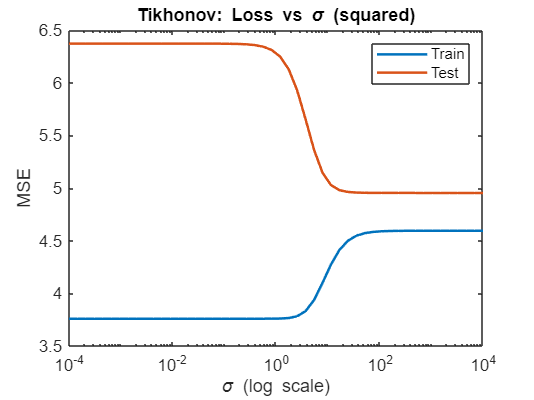

train_loss2 = zeros(size(sigmas));
test_loss2 = zeros(size(sigmas));
for i = 1:length(sigmas)
    s2 = sigmas(i)^2;
    I = diag([ones(n,1);0]); % no intercept
    w2 = (X1' * X1 + s2 * I) \ (X1' * y);
    ytr2 = X1 * w2;
    yte2 = [Xtest, ones(Ntest,1)] * w2;
    train_loss2(i) = mean((y - ytr2).^2);
    test_loss2(i)  = mean((ytest - yte2).^2);
end

figure;
semilogx(sigmas, train_loss2, 'LineWidth', 1.5); hold on;
semilogx(sigmas, test_loss2, 'LineWidth', 1.5);
title('Tikhonov: Loss vs \sigma (squared)');
xlabel('\sigma (log scale)'); ylabel('MSE');
legend('Train','Test');

### F. Constrained Models Based on y Thresholds

To explore domain‐specific modeling, we train two separate ridge regressors under sample constraints: one using only observations with y ≥ 0.5 and another (hypothetically) with y ≤ –0.5. Applying a fixed σ² penalty (e.g. σ = 1) to each subset, we then evaluate their test MSEs against the baseline OLS model. This experiment shows how imposing data-driven thresholds can alter generalization performance.

% Model 1: train on samples with y >= 0.5
idx1 = y >= 0.5;
X1_c1 = [X(idx1,:), ones(sum(idx1),1)]; y1 = y(idx1);
w1 = (X1_c1' * X1_c1 + sigmas(10)^2 * diag([ones(n,1);0])) \ (X1_c1' * y1);

% Model 2: train on samples with y <= -0.5 (here none, but demonstrate)
idx2 = y <= -0.5;
if any(idx2)
    X1_c2 = [X(idx2,:), ones(sum(idx2),1)]; y2 = y(idx2);
    w2_c = (X1_c2' * X1_c2 + sigmas(10)^2 * diag([ones(n,1);0])) \ (X1_c2' * y2);
else
    w2_c = NaN(n+1,1);
end

% Evaluate both on test set
y_pred1_test = [Xtest, ones(Ntest,1)] * w1;
MSE1 = mean((ytest - y_pred1_test).^2);

if ~isnan(w2_c)
    y_pred2_test = [Xtest, ones(Ntest,1)] * w2_c;
    MSE2 = mean((ytest - y_pred2_test).^2);
else
    MSE2 = NaN;
end

fprintf('Constrained Model1 (y>=0.5) Test MSE: %.4f\n', MSE1);

Constrained Model1 (y>=0.5) Test MSE: 6.1763


fprintf('Constrained Model2 (y<=-0.5) Test MSE: %.4f\n', MSE2);

Constrained Model2 (y<=-0.5) Test MSE: NaN



% Compare to baseline
fprintf('Baseline OLS Test MSE: %.4f\n', MSE_test);

Baseline OLS Test MSE: 6.3708



% Note: Since y is Poisson >=0, idx2 yields no samples => no model2.
